clear all;

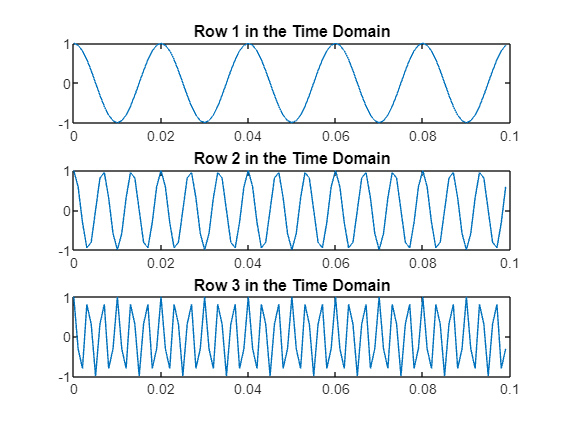

% FFT example - Cosine Waves (taken from
% https://se.mathworks.com/help/matlab/ref/fft.html#buuutyt-10)

% Compare cosine waves in the time domain and the frequency domain.
% Specify the parameters of a signal with a sampling frequency of 1 kHz and
% a signal duration of 1 second.
Fs = 1000;                    % Sampling frequency
T = 1/Fs;                     % Sampling period
L = 1000;                     % Length of signal
t = (0:L-1)*T;                % Time vector

% Create a matrix where each row represents a cosine wave with scaled
% frequency. The result, X, is a 3-by-1000 matrix. The first row has a wave
% frequency of 50, the second row has a wave frequency of 150, and the
% third row has a wave frequency of 300.
x1 = cos(2*pi*50*t);          % First row wave
x2 = cos(2*pi*150*t);         % Second row wave
x3 = cos(2*pi*300*t);         % Third row wave

X = [x1; x2; x3];

% Plot the first 100 entries from each row of X in a single figure in order
% and compare their frequencies.
figure
for i = 1:3
    subplot(3,1,i)
    plot(t(1:100),X(i,1:100))
    title("Row " + num2str(i) + " in the Time Domain")
end

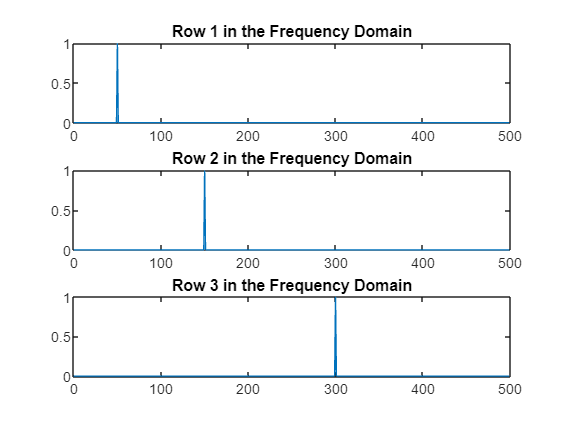


% Specify the dim argument to use fft along the rows of X, that is, for
% each signal.
dim = 2;

% Compute the Fourier transform of the signals.
Y = fft(X,L,dim);

% Calculate the double-sided spectrum and single-sided spectrum of each
% signal.
P2 = abs(Y/L);
P1 = P2(:,1:L/2+1);
P1(:,2:end-1) = 2*P1(:,2:end-1);

% In the frequency domain, plot the single-sided amplitude spectrum for
% each row in a single figure
figure
for i=1:3
    subplot(3,1,i)
    plot(0:(Fs/L):(Fs/2-Fs/L),P1(i,1:L/2))
    title("Row " + num2str(i) + " in the Frequency Domain")
end